clc;clear;

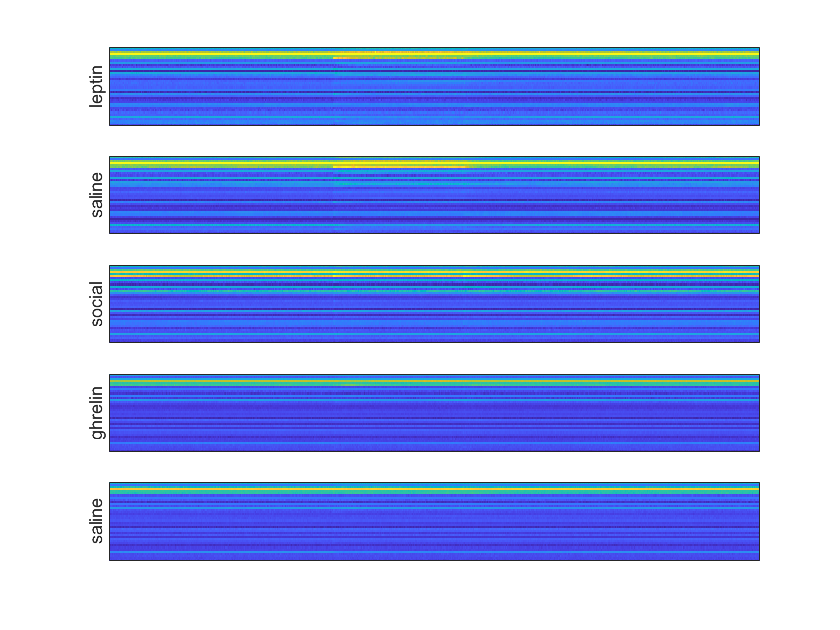

clSigN = {'leptin','saline','social','ghrelin','saline'};
clResps = cell(5,1);
clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D2\Reg_Cat\Resp_SubRing_v3.mat');
clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D3\Reg_Cat\Resp_SubRing_v3.mat');
clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D5\Reg_Cat\Resp_SubRing_v3.mat');
clResps{4} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D8\Reg_Cat\Resp_SubRing_v3.mat');
clResps{5} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D9\Reg_Cat\Resp_SubRing_v3.mat');
Num_all = [10,12,12,16,16]; % 492241
clims = [0 50];
figure;
for n=1:5    
    subplot(5,1,n);
    if n == 4
        Num_n = Num_all(n)- 4;% remove 1-4: 1st (intensity low), 3,4,5th trial.
        matResp = clResps{n}.matResp(:,1360*4+1:end);
    elseif n == 5
        Num_n = Num_all(n)- 4; % remove 1-4: 1st (intensity low), 2,3,4th trial.
        matResp = clResps{n}.matResp(:,1360*4+1:end);   
    else
        Num_n = Num_all(n); 
        matResp = clResps{n}.matResp;       
    end
    
    matResp = reshape(matResp,size(matResp,1),size(matResp,2)/Num_n,Num_n);
    % dividable 
    result = squeeze(mean(matResp,3)); % % dividable 
    imagesc(result,clims);  % average
    set(gca,'xtick',[],'ytick',[])
    ylabel(clSigN{n});
end

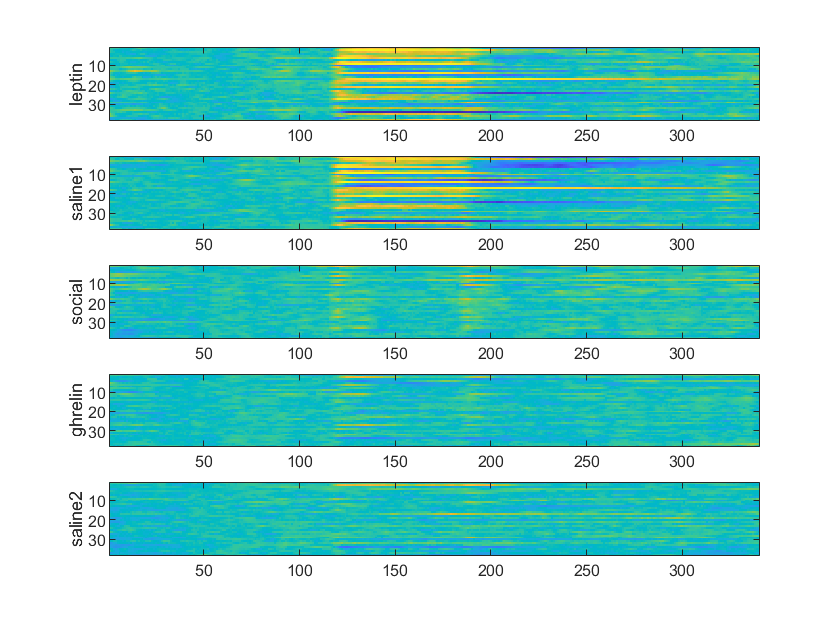

   
clSigN = {'leptin','saline1','social','ghrelin','saline2'};
clResps = cell(5,1);
clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D2\Reg_Cat\Resp_SubRing_v3.mat');
clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D3\Reg_Cat\Resp_SubRing_v3.mat');
clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D5\Reg_Cat\Resp_SubRing_v3.mat');
clResps{4} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D8\Reg_Cat\Resp_SubRing_v3.mat');
clResps{5} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D9\Reg_Cat\Resp_SubRing_v3.mat');
Num_all = [10,12,12,16,16]; % 492241
        
%% parameter for Auroc
vtEvents = [156,157,272];% event for behavior? vtFrm
Frm = 1360;
AvgFrm = 4;%3
idxTN_Rg =[round(20*Frm/175) round(40*Frm/175)]; % True negative
szBin= round(2*Frm/175); % 5
clims = [-1 1];

figure;
for n=1:5    
    subplot(5,1,n);
    if n == 4
        Num_n = Num_all(n)- 4;% remove 1-4: 1st (intensity low), 3,4,5th trial.
        matResp = clResps{n}.matResp(:,1360*4+1:end);
    elseif n == 5
        Num_n = Num_all(n)- 4; % remove 1-4: 1,2,3,4th trial.
        matResp = clResps{n}.matResp(:,1360*4+1:end);      
    else
        Num_n = Num_all(n); 
        matResp = clResps{n}.matResp;       
    end
    
    matResp1 = NormResROC_v1(matResp,idxTN_Rg,Num_n,szBin,AvgFrm);
        % save in mat
        clResps_x{n}(1) = {matResp};
        clResps_x{n}(2) = {NormMatRow(matResp)};
        clResps_x{n}(3) = {matResp1};
        % save('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D7\Reg_Cat\Resp_SubRing_v3.mat');     
        imagesc(matResp1,clims);  % average
        
%         set(gca,'xtick',[],'ytick',[])
        ylabel(clSigN{n});
end

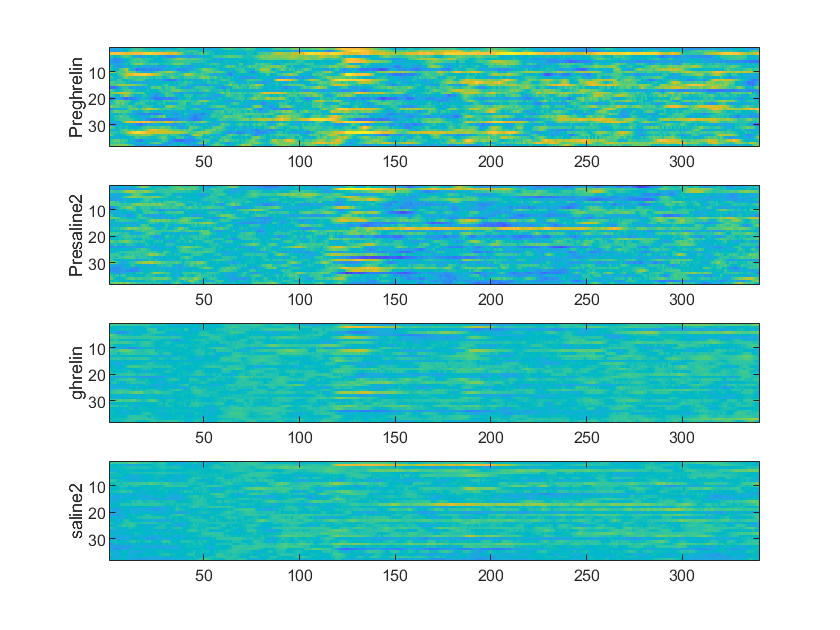

% only for compare before and after ghrelin and saline2 injection
clSigN = {'Preghrelin','Presaline2','ghrelin','saline2'};
clResps = cell(4,1);
clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D8\Reg_Cat\Resp_SubRing_v3.mat');
clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D9\Reg_Cat\Resp_SubRing_v3.mat');
clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D8\Reg_Cat\Resp_SubRing_v3.mat');
clResps{4} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D9\Reg_Cat\Resp_SubRing_v3.mat');
Num_all = [3,4,12,12]; % 492241
        
%% parameter for Auroc
vtEvents = [156,157,272];% event for behavior? vtFrm
Frm = 1360;
AvgFrm = 4;%3
idxTN_Rg =[round(20*Frm/175) round(40*Frm/175)]; % True negative
szBin= round(2*Frm/175); % 5
clims = [-1 1];

figure;
for n=1:4    
    subplot(4,1,n);
    if n == 1
        Num_n = Num_all(n);% 2-4: 1st (intensity low), 3,4,5th trial.
        matResp = clResps{n}.matResp(:,1360+1:1360*4);
    elseif n == 2
        Num_n = Num_all(n); %  1-4: 1,2,3,4th trial.
        matResp = clResps{n}.matResp(:,1:1360*4); 
    elseif n == 3
        Num_n = Num_all(n); % remove 1-4: 1st (intensity low), 3,4,5th trial.
        matResp = clResps{n}.matResp(:,1360*4+1:end); 
    else
        Num_n = Num_all(n); % remove 1-4: 1, 2,3,4th trial.
        matResp = clResps{n}.matResp(:,1360*4+1:end);       
    end
    
    matResp1 = NormResROC_v1(matResp,idxTN_Rg,Num_n,szBin,AvgFrm);
    % save in mat
    clResps_x{n}(1) = {matResp};
    clResps_x{n}(2) = {NormMatRow(matResp)};
    clResps_x{n}(3) = {matResp1};
    % save('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D7\Reg_Cat\Resp_SubRing_v3.mat');     
    imagesc(matResp1,clims);  % average
%         set(gca,'xtick',[],'ytick',[])
    ylabel(clSigN{n});
end

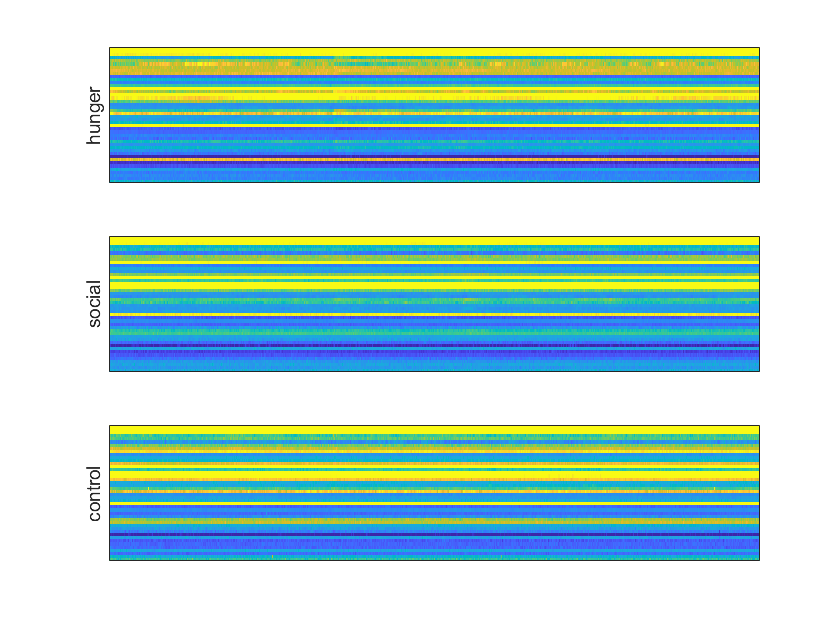

% raw
aa=1;
clSigN = {'hunger','social','control'};
clResps = cell(3,1);

if aa == 1
clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1211\Reg_Cat\Resp_SubRing_v3.mat');
clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1212\Reg_Cat\Resp_SubRing_v3.mat');
clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1213\Reg_Cat\Resp_SubRing_v3.mat');
Num_all = [10,10,9]; % 496190

elseif aa == 2
clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496191\1211\Reg_Cat\Resp_SubRing_v3.mat');
clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496191\1212\Reg_Cat\Resp_SubRing_v3.mat');
clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496191\1213\Reg_Cat\Resp_SubRing_v3.mat');
Num_all = [10,10,10]; % 496191
else
clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D1\Reg_Cat\Resp_SubRing_v3.mat');
clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D6\Reg_Cat\Resp_SubRing_v3.mat');
clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D7\Reg_Cat\Resp_SubRing_v3.mat');
Num_all = [10,13,13]; % 492241
end

clims = [0 50];
figure;
for n=1:3    
    subplot(3,1,n);
    Num_n = Num_all(n); 
    matResp = clResps{n}.matResp;
    matResp = reshape(matResp,size(matResp,1),size(matResp,2)/Num_n,Num_n);
    result = squeeze(mean(matResp,3)); % % dividable 
    imagesc(result,clims);  % average
    set(gca,'xtick',[],'ytick',[])
    ylabel(clSigN{n});
end

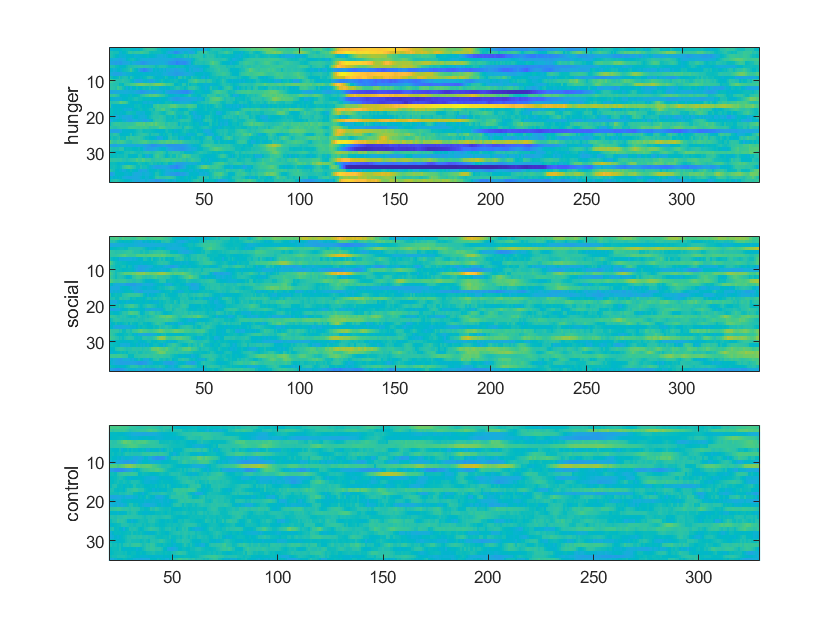

% raw to auroc
for aa=3
    clSigN = {'hunger','social','control'};
    clResps = cell(3,1);
    
    if aa == 1
    clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1211\Reg_Cat\Resp_SubRing_v3.mat');
    clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1212\Reg_Cat\Resp_SubRing_v3.mat');
    clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496190_visual_guidence\1213\Reg_Cat\Resp_SubRing_v3.mat');
    Num_all = [10,10,9]; % 496190
    
    elseif aa == 2
    clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496191\1211\Reg_Cat\Resp_SubRing_v3.mat');
    clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496191\1212\Reg_Cat\Resp_SubRing_v3.mat');
    clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\ANM496191\1213\Reg_Cat\Resp_SubRing_v3.mat');
    Num_all = [10,10,10]; % 496191
    else
    clResps{1} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D1\Reg_Cat\Resp_SubRing_v3.mat');
    clResps{2} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D6\Reg_Cat\Resp_SubRing_v3.mat');
    clResps{3} = load('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D7\Reg_Cat\Resp_SubRing_v3.mat');
    Num_all = [10,13,13]; % 492241
    end
    
    
    %% parameter for Auroc
    vtEvents = [156,157,272];% event for behavior? vtFrm
    Frm = 1360;
    AvgFrm = 4;%3
    idxTN_Rg =[round(20*Frm/175) round(40*Frm/175)]; % True negative
    szBin= round(2*Frm/175); % 5
    
    clims = [-1 1];
    figure;
    for n=1:3    
        subplot(3,1,n);
        Num_n = Num_all(n); 
        matResp = clResps{n}.matResp;
        matResp1 = NormResROC_v1(matResp,idxTN_Rg,Num_n,szBin,AvgFrm);
        % save in mat
        clResps_x{n}(1) = {matResp};
        clResps_x{n}(2) = {NormMatRow(matResp)};
        clResps_x{n}(3) = {matResp1};
        % save('Z:\Zhenggang\CaRMApipeline\Example_Data\ANM378231\Fear_Imaging_Exp\492241\D7\Reg_Cat\Resp_SubRing_v3.mat');     
        imagesc(matResp1,clims);  % average
        
         set(gca,'xtick',[],'ytick',[])
        ylabel(clSigN{n});
    end
end

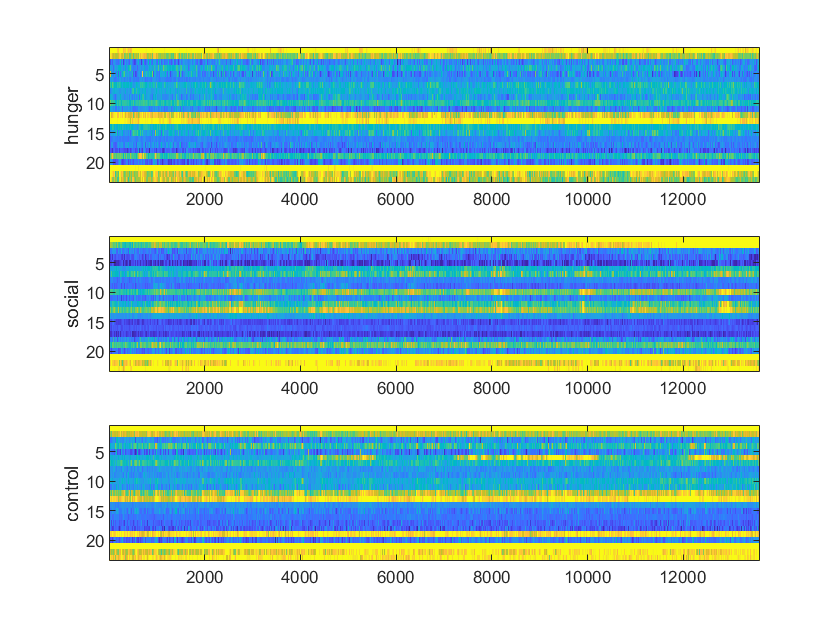

load('Z:\Zhenggang\D_disk_01202022\6_CaRMA_imaging\nbg1_ANM492241\Resp_ANM496191_Roc.mat')
clSigN = {'hunger','social','control'};
clims = [0 50];
figure;
for n=1:3    
    
    if n == 2
        N = 3;
    elseif n == 3
        N = 2;
    else
        N = 1;
    end
    
    subplot(3,1,n);
    aa = clResps_x{N}(1);
    imagesc(aa{1,1},clims);  % average
%     set(gca,'xtick',[],'ytick',[])
    ylabel(clSigN{n});
end

% normalize and average
Num_all = [10,10,9]; 
figure;
for n=1:3    
    subplot(3,1,n);
    Num_n = Num_all(n); 
    result = squeeze(mean(reshape(NormMatCol(clResps{n}.matResp),size(NormMatCol(clResps{n}.matResp),1),Num_n,[]),2));  % dividable 
    imagesc(result);  % average
    set(gca,'xtick',[],'ytick',[])
    ylabel(clSigN{n});
end